# **Homework 3 Sol. (OCDR)**

**Universidad Nacional de Colombia**

**By:**

- Santiago Cadena Álvarez (Electrical Engineering student)

**To: **

Eng. Eduardo A. Mojica - Nava

## **1) Consensus-Based Optimization and Distributed ADMM**

**1.** Consider the graph in Figure 1. Assume that each $x_i$ is a copy of the variable for that node, $x_i \;\epsilon \;\Re$ and each node has a local cost function as follows: $f_i \left(x\right)=2\textrm{ix}+{\textrm{ix}}^2$ with $i=1,2,\ldotp \ldotp \ldotp ,5$. (For instance if $i=1,\;f_1 \left(x\right)=2x+x^2$).

Consider the optimization problem


$$\begin{array}{l}
\min \;F\left(x\right)=\sum_{i=1}^m f_i \left(x\right)\\
s\ldotp t\ldotp \;x\;\epsilon \;X
\end{array}$$


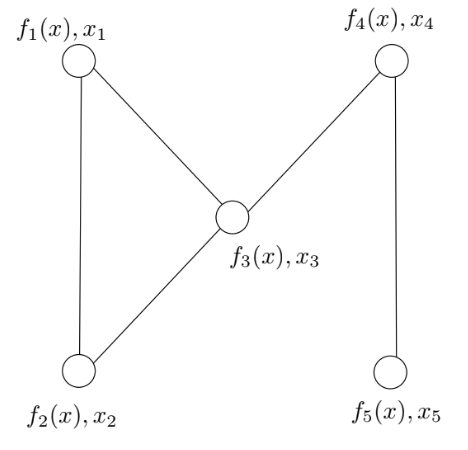


$$\nabla f_i \left(x\right)=2i+2\textrm{ix}=2i\left(1+x\right)$$


**(a)** Consider that $X=\Re$. Obtain a suitable matrix A to guarantee convergence of the distributed** consensus-based** algorithm and solve the problem using Matlab/Python

Because of {$G_t$} is a sequence of undirected graphs, {A(t)} can be a sequence of m × m matrices such that the following conditions hold: 

- Each A(t) is a **doubly stochastic matrix **that is compliant with the graph Gt , i.e., Aij(t) > 0 whenever {i, j} ∈ Et for t ≥ 0.

-  **(Aperiodicity)** The diagonal entries of each A(t) are positive, Aii(t) > 0 for all t and i. 

- **(Uniform Posivity)** There is a scalar β > 0 such that Aij(t) ≥ β whenever Aij(t) > 0. 

- **(Irreducibility)** Each graph Gt is connected. 

The Laplacian is:


$$L=\left\lbrack \begin{array}{ccccc}
2 & -1 & -1 & 0 & 0\\
-1 & 2 & -1 & 0 & 0\\
-1 & -1 & 3 & -1 & 0\\
0 & 0 & -1 & 2 & -1\\
0 & 01 & 0 & -1 & 1
\end{array}\right\rbrack$$



$$A=\left(I-\alpha L\right)$$



$$A=\left\lbrack \begin{array}{ccccc}
1-2\alpha  & \alpha  & \alpha  & 0 & 0\\
\alpha  & 1-2\alpha  & \alpha  & 0 & 0\\
\alpha  & \alpha  & 1-3\alpha  & \alpha  & 0\\
0 & 0 & \alpha  & 1-2\alpha  & \alpha \\
0 & 0 & 0 & \alpha  & 1-\alpha 
\end{array}\right\rbrack$$


Choosing any $\alpha$, the matrix remains double stochastic. However to acomplish the requeriment of aperiodicity and uniform posivity, the following has to be true:


$$\begin{array}{l}
\alpha >0\\
1-2\alpha >0\\
0<\alpha <\frac{1}{2}
\end{array}$$


I choose $\alpha =\frac{1}{4}$ arbitrary.

The algorithm for finding x is the following:


$$x_i^{k+1} =A_{\textrm{ij}} \sum_{j\;\epsilon \;N_i } x_j^k -\alpha \nabla f_i \left(A_{\textrm{ij}} \sum_{j\;\epsilon \;N_i } x_j^k \right)x_j^k$$


It's seen that it only takes account the vecinity nodes.

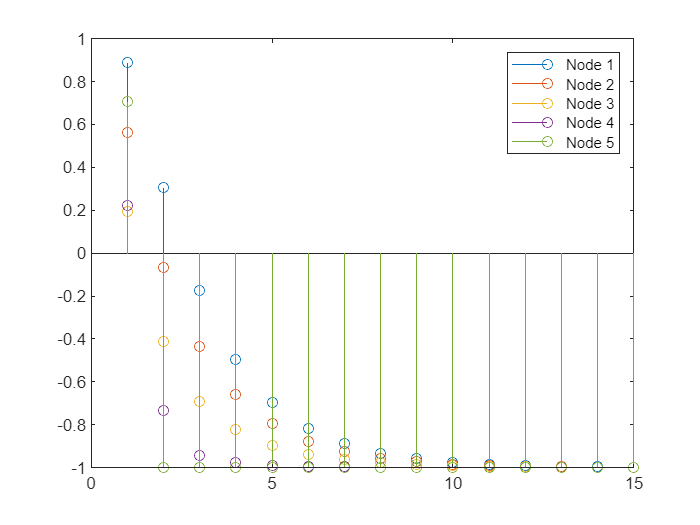

clc
clear 

alpha=0.25;
A = [(1-2*alpha), alpha, alpha, 0, 0;
     alpha, 1-2*alpha, alpha, 0, 0;
     alpha, alpha, 1-3*alpha, alpha, 0;
     0, 0, alpha, 1-2*alpha	, alpha;
     0, 0, 0, alpha, 1-alpha];
A_ij=A.*[0,1,1,1,1;1,0,1,1,1;1,1,0,1,1;1,1,1,0,1;1,1,1,1,0];

% Number of nodes (5)
m = size(A, 1);
% Generate distributed initial conditions randomly in the interval [-5, 5]
x0 = rand(m, 1);
% The solution to the concensus equation in discrete time is iterative
max_it=500;
x=zeros(m,max_it);
x(:,1)=x0;
epsilon=1E-3;
k=1;
a=0.1;
%define the gradient for each node
gradf=@(i,arg)2*i*(1+arg);
%Till reaching an error < epsilon any(abs(diff(x(:,k)))>epsilon)
while(any(abs(diff(x(:,k)))>epsilon))

        w(:,k)=A*x(:,k);
        %gradient evaluated in w(i)
        grad=[gradf(1,w(1,k)) gradf(2,w(2,k)) gradf(3,w(3,k)) gradf(4,w(4,k)) gradf(5,w(5,k)) ]';
        %grad=[df1 df df3 df4 df5]';
        x(:,k+1)=A*x(:,k)-a*grad; 
        k=k+1;
end


% Plot the discrete time response for each node
figure
for i = 1:m
    stem(1:k,x(i,1:k))
    hold on;
end

legend('Node 1','Node 2','Node 3','Node 4','Node 5');

 **(b)** Consider now that $X=\left\lbrack -1,2\right\rbrack$ and repeat 

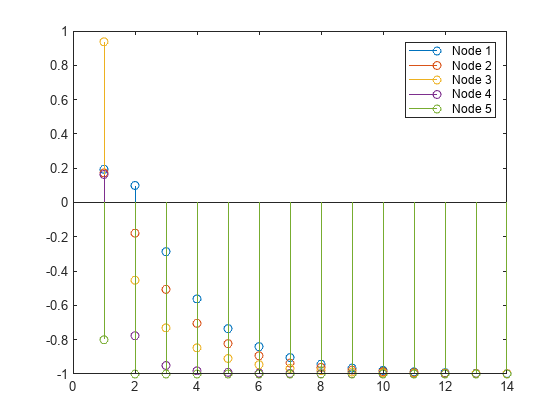

% Generate distributed initial conditions randomly in the interval [-1, 2]
x0 = -1+2*rand(m, 1);
% The solution to the concensus equation in discrete time is iterative
x=zeros(m,max_it);
x(:,1)=x0;
k=1;
%Till reaching an error < epsilon
while(any(abs(diff(x(:,k)))>epsilon))
        w(:,k)=A*x(:,k);
        %gradient evaluated in w(i)
        grad=[gradf(1,w(1,k)) gradf(2,w(2,k)) gradf(3,w(3,k)) gradf(4,w(4,k)) gradf(5,w(5,k)) ]';
        x(:,k+1)=A*x(:,k)-a*grad; 
        k=k+1;
end

% Plot the discrete time response for each node

figure
for i = 1:m
    stem(1:k,x(i,1:k))
    hold on;
end
%}
legend('Node 1','Node 2','Node 3','Node 4','Node 5');

**(c)** Consider again that $X=\Re$, but $A\left(t\right)$ is time-varying. Solve the problem using Matlab/Python. Show the evolution of the iteration $x_i \left(k\right)\;\textrm{vs}\;k$

Consider the case of time-varying undirected graphs {Gt}. The algorithm of the updates is

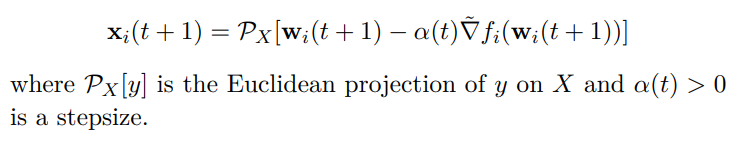

This time, $\alpha$ and $A$are changing with time. So in each iteration for $x_i$ i produce a new double stochastic matrix A.

% Generate distributed initial conditions randomly
x0 = rand(m, 1);
% The solution to the concensus equation in discrete time is iterative
x=zeros(m,max_it);
x(:,1)=x0;
k=1;
%Till reaching an error < epsilon 
while(any(abs(diff(x(:,k)))>epsilon))

    alpha=0.5*rand(1);
    A = [(1-2*alpha), alpha, alpha, 0, 0;
     alpha, 1-2*alpha, alpha, 0, 0;
     alpha, alpha, 1-3*alpha, alpha, 0;
     0, 0, alpha, 1-2*alpha	, alpha;
     0, 0, 0, alpha, 1-alpha];
    A_ij=A.*[0,1,1,1,1;1,0,1,1,1;1,1,0,1,1;1,1,1,0,1;1,1,1,1,0];
    %find x(k+1) for all the nodes
    w(:,k)=A*x(:,k);
    %gradient evaluated in w(i)
    grad=[gradf(1,w(1,k)) gradf(2,w(2,k)) gradf(3,w(3,k)) gradf(4,w(4,k)) gradf(5,w(5,k)) ]';
    x(:,k+1)=A*x(:,k)-a*grad; 
    k=k+1;

end

% Plot the discrete time response for each node

figure
for i = 1:m
    stem(1:k,x(i,1:k))
    hold on;
end
%}
legend('Node 1','Node 2','Node 3','Node 4','Node 5');

With the convergence assured, the matrix A is finally:

A

A =     0.3730    0.3135    0.3135         0         0
    0.3135    0.3730    0.3135         0         0
    0.3135    0.3135    0.0596    0.3135         0
         0         0    0.3135    0.3730    0.3135
         0         0         0    0.3135    0.6865


**2.** Randomly generate an undirected graph of 25 nodes. Set the dimension of the state $x\in \Re^3$. For each agent create a 3 × 3 matrix $M_i$ and vector $b_i$ with entries from an interval [0.1, 1]. Solve the optimization problem:


$$\min \;\sum_{i=1}^m f_i \left(x\right)$$



$$f_i \left(x\right)={||xM_i -b_i ||}^2$$


which is a distributed optimization problem. Solve using Matlab/Python and analyze the convergence from a **computational viewpoint **(no theoretical analysis). Show a step by step figure of each $x_i$ (only two coordinates are needed).

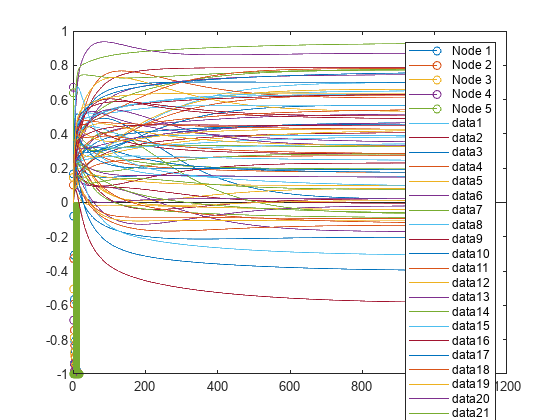

clc 
clear

a=0.05;

M1=[.5 .2 .4;.7 .9 .5;1 .3 .8];
M2=[.5 .4 .4;.1 .7 .4;.7 .4 1];
M3=[.7 .4 .6;.7 .9 .4;.4 .5 1];
M4=[1 1 .8;1 .1 .9;.7 1 .1];
M5=[.6 .8 .2;.5 1 .5;.2 .4 .3];
M6=[1 1 .4;1 .2 .4;.6 .5 .8];
M7=[.8 .9 .2;.1 .9 .7;.9 .2 .3];
M8=[.9 .2 .1;.7 .5 .3;.2 .7 1];
M9=[1 .1 .7;.1 .5 1;.2 1 .5];
M10=[.9 .3 .8;.6 .6 .2;.1 .2 .3];
M11=[.6 .5 .9;.7 1 .5;.1 .2 .6];
M12=[.2 .3 .1;.2 .9 .4;.5 .7 .1];
M13=[.7 .3 .6;.9 .7 .4;.5 .4 .6];
M14=[.8 .6 .9;.7 .9 .1;.8 .8 .8];
M15=[.5 .4 .7;.1 .1 .9;1 .3 .5];
M16=[.7 .6 1;.9 .5 .9;.4 .8 .2];
M17=[.4 .1 1;.7 .1 .7;1 .2 .2];
M18=[.7 .8 .7;.6 .9 .6;.6 .9 .1];
M19=[.7 .3 .9;1 .1 .7;.9 .8 .5];
M20=[.7 .3 .1;1 .1 .7;.9 .8 .5];
M21=[.8 .3 .2;.7 .4 .7;.2 .5 .2];
M22=[.4 .6 .7;.5 .3 .4;.7 .1 .7];
M23=[.9 .6 1;.4 .6 .6;.6 .6 .5];
M24=[.8 .1 1;.6 .5 .8;.5 .2 .3];
M25=[.9 .6 1;.9 .9 .2;.1 .4 1];

b1=[.5 .5 .6]';
b2=[.1 .1 .3]';
b3=[.9 .4 .4]';
b4=[.4 .3 .8]';
b5=[.2 .3 .4]';
b6=[.2 .3 .7]';
b7=[.3 .3 .2]';
b8=[.8 1 .3]';
b9=[.2 .1 .1]';
b10=[.9 .6 .9]';
b11=[.1 .4 1]';
b12=[.6 .6 .2]';
b13=[.2 .5 .1]';
b14=[.9 .8 .7]';
b15=[.9 .2 .2]';
b16=[.8 .9 .6]';
b17=[.9 .4 .2]';
b18=[.2 .5 .7]';
b19=[.4 .3 .6]';
b20=[.3 .9 .4]';
b21=[.8 .1 1]';
b22=[1 .7 .5]';
b23=[.3 .6 1]';
b24=[.8 1 1]';
b25=[.9 1 .9]';

ceros=zeros(75);

x=ceros(:,1);
df=ceros(:,1);

L=[1 0 0 0 0 0 -1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0
   0 2 -1 0 0 0 -1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0
   0 -1 2 0 0 0 0 -1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0
   0 0 0 2 -1 0 0 -1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0
   0 0 0 -1 2 0 0 0 0 -1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 
   0 0 0 0 0 1 0 0 0 0 -1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 
   -1 -1 0 0 0 0 3 0 0 0 -1 0 0 0 0 0 0 0 0 0 0 0 0 0 0
   0 0 -1 -1 0 0 0 5 -1 0 0 -1 -1 0 0 0 0 0 0 0 0 0 0 0 0
   0 0 0 0 0 0 0 -1 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 
   0 0 0 0 -1 0 0 0 0 2 0 0 0 0 -1 0 0 0 0 0 0 0 0 0 0
   0 0 0 0 0 -1 -1 0 0 0 4 0 0 0 0 -1 -1 0 0 0 0 0 0 0 0
   0 0 0 0 0 0 0 -1 0 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0
   0 0 0 0 0 0 0 -1 0 0 0 0 2 0 0 0 0 -1 0 0 0 0 0 0 0
   0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 -1 0 0 0 0 0 0
   0 0 0 0 0 0 0 0 0 -1 0 0 0 0 2 0 0 0 -1 0 0 0 0 0 0
   0 0 0 0 0 0 0 0 0 0 -1 0 0 0 0 1 0 0 0 0 0 0 0 0 0
   0 0 0 0 0 0 0 0 0 0 -1 0 0 0 0 0 2 0 0 0 -1 0 0 0 0
   0 0 0 0 0 0 0 0 0 0 0 0 -1 0 0 0 0 2 0 0 0 -1 0 0 0
   0 0 0 0 0 0 0 0 0 0 0 0 0 -1 -1 0 0 0 4 0 0 0 -1 0 -1
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 0 0 0 0 -1
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 -1 0 0 0 1 0 0 0 0
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 -1 0 0 0 2 -1 0 0
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 -1 0 0 -1 2 0 0
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 -1
   0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 -1 -1 0 0 0 -1 3];

A=eye(25)-1/25*L;

kr=kron(A,eye(3));

for i=1:1000

    df1=2*M1*(M1*x(1:3,i)-b1);
    df2=2*M2*(M2*x(4:6,i)-b2);
    df3=2*M3*(M3*x(7:9,i)-b3);
    df4=2*M4*(M4*x(10:12,i)-b4);
    df5=2*M5*(M5*x(13:15,i)-b5);
    df6=2*M6*(M6*x(16:18,i)-b6);
    df7=2*M7*(M7*x(19:21,i)-b7);
    df8=2*M8*(M8*x(22:24,i)-b8);
    df9=2*M9*(M9*x(25:27,i)-b9);
    df10=2*M10*(M10*x(28:30,i)-b10);
    df11=2*M11*(M11*x(31:33,i)-b11);
    df12=2*M12*(M12*x(34:36,i)-b12);
    df13=2*M13*(M13*x(37:39,i)-b13);
    df14=2*M14*(M14*x(40:42,i)-b14);
    df15=2*M15*(M15*x(43:45,i)-b15);
    df16=2*M16*(M16*x(46:48,i)-b16);
    df17=2*M17*(M17*x(49:51,i)-b17);
    df18=2*M18*(M18*x(52:54,i)-b18);
    df19=2*M19*(M19*x(55:57,i)-b19);
    df20=2*M20*(M20*x(58:60,i)-b20);
    df21=2*M21*(M21*x(61:63,i)-b21);
    df22=2*M22*(M22*x(64:66,i)-b22);
    df23=2*M23*(M23*x(67:69,i)-b23);
    df24=2*M24*(M24*x(70:72,i)-b24);
    df25=2*M25*(M25*x(73:75,i)-b25);
    
    df=[df1;df2;df3;df4;df5;df6;df7;df8;df9;df10;df11;df12;df13;df14;df15;df16;df17;df18;df19;df20;df21;df22;df23;df24;df25];
        
    x(:,i+1)=kr*x(:,i)-a*df;
 
end

k=1:1001;

plot(k,x)

**3. **Consider again Problem in 1. (Figure 1) with $X=\Re$. Assume all you need to solve the problem using a **Distributed ADMM**. Solve the problem using Matlab/Python. Show the evolution of the iteration $x_i \left(k\right)\;\textrm{vs}\;k$. Make a comparative analysis of performance (in words) between consensus-based and DADMM.

**(a)** Consider that $X=\Re$. Obtain a suitable matrix A to guarantee convergence of the distributed** consensus-based** algorithm and solve the problem using Matlab/Python

It's possible to reformule the problem of optimization using the ADMM form :


$$\begin{array}{l}
\min \;\sum_{i=1}^m f_i \left(x_i \right)\\
s\ldotp t\ldotp {\;\;x}_i -z=0
\end{array}$$


Where $x$ is the local vairable, and z is the global variable. $x-z=0$ is the concensus constraint.


$$L_p =\sum_{i=1}^5 \left(f_i \left(x_i \right)+\mu_i \left(x_i -z\right)\right)+\rho {||x_i -z||}_2^2 +g\left(z\right)$$


Where g(z) is a term that uses regulatization for improving the optimization, or overfitting. In this case I choose $g\left(z\right)=0$.


$$\begin{array}{l}
{x_i }^{k+1} =\underset{x}{\arg \;\min \;L_p \left(x_i ,z^k ,\mu^k \right)} =\underset{x}{\arg \;\left(\;\nabla {L_p }_x \right)} =0\\
0=2i+2i{\mathrm{x}}_i +\mu_i +2\rho \left({\mathrm{x}}_i -z\right)\\
{x_i }^{k+1} =\frac{2\rho z^k -2i-\mu_i^k }{2i+2\rho }\\
z^{k+1} =\arg \;\min \;L_p \left(x_i^{k+1} ,z,\mu_i^k \right)=\frac{1}{5}\sum_{i=1}^5 \left(x_i^{k+1} +\left(\frac{1}{\rho }\right)\mu_i^k \right)\\
\mu_i^{k+1} =\mu_i^k +\rho \left(x_i^{k+1} -z^{k+1} \right)
\end{array}$$


The matrix A can be obtained this way: 


$$x_i^{k+1} =A_{\textrm{ij}} \left(\sum_{j\;\epsilon \;N_i } x_j^k -\alpha \nabla f_i x_j^k \right)$$


The matrix is caracterized by the null diagonal values beacuse only take account the neighborhood $N_i$, and the conections among the nodes, hence if there's no connection the element in the matrix is null. In this case:


$$x_i^{k+1} =A_{\textrm{ij}} \;\sum_{j\;\epsilon \;N_i } x_j^k \;\left(1-\alpha \nabla f_i \right)=\left\lbrack \begin{array}{ccccc}
0 & x_2^k \left(1-\alpha \nabla f_1 \right) & x_3^k \left(1-\alpha \nabla f_1 \right) & 0 & 0\\
x_1^k \left(1-\alpha \nabla f_2 \right) & 0 & x_3^k \left(1-\alpha \nabla f_2 \right) & 0 & 0\\
x_1^k \left(1-\alpha \nabla f_3 \right) & x_2^k \left(1-\alpha \nabla f_3 \right) & 0 & x_4^k \left(1-\alpha \nabla f_3 \right) & 0\\
0 & 0 & x_3^k \left(1-\alpha \nabla f_4 \right) & 0 & x_5^k \left(1-\alpha \nabla f_4 \right)\\
0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \;$$

$$\left\lbrack \begin{array}{c}
A_1 \\
A_2 \\
A_3 \\
A_4 \\
A_5 
\end{array}\right\rbrack$$



$$A_i ={\left(\sum_{j\;\epsilon \;N_i } x_j^k -\alpha \nabla f_i x_j^k \right)}^{-1} x_i^{k+1}$$


After making the inverse and make the multiplication, due to the equivalence we can obtain the matrix A definitely:


$$A=\left\lbrack \begin{array}{c}
A_1 \\
A_2 \\
A_3 \\
A_4 \\
A_5 
\end{array}\right\rbrack \;\left\lbrack \begin{array}{ccccc}
0 & \left(1-\alpha \nabla f_1 \right) & \left(1-\alpha \nabla f_1 \right) & 0 & 0\\
\left(1-\alpha \nabla f_2 \right) & 0 & \left(1-\alpha \nabla f_2 \right) & 0 & 0\\
\left(1-\alpha \nabla f_3 \right) & \left(1-\alpha \nabla f_3 \right) & 0 & \left(1-\alpha \nabla f_3 \right) & 0\\
0 & 0 & \left(1-\alpha \nabla f_4 \right) & 0 & \left(1-\alpha \nabla f_4 \right)\\
0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


clc
clear
%parameters
rho=0.6; %arbitrary choice
N=5; %number of nodes
alpha=0.5; %stepsize of gradient ascend 
%Initial conditions
z=rand(1,100);
mu=zeros(5,100);
mu(:,1)=max(0,rand(5,1)); %Initial values for each mu(<0). There's a mu for each restriction xi-z=0
x=zeros(5,100);
x(:,1)=rand(5,1);
%Error
epsilon=1E-3; %Minimum difference between x and mu
k=1;

while(any(abs(x(:,k)-z)>epsilon))
    %First, find x(k+1) for all the nodes
    for i=1:N
        x(i,k+1)=((2*rho)*z(k)-2*i-mu(i,k))/(2*i+rho*2);
    end    
    Matrix=zeros(5);
    gradf=@(i)2*i*(1-alpha*x(i,k));
    M=2*[0 gradf(1) gradf(1) 0 0;
     gradf(2) 0 gradf(2) 0 0;
     gradf(3) gradf(3) 0 gradf(3) 0;
     0 0 gradf(4) 0 gradf(4);
     0 0 0 gradf(5) 0];

    z(k+1)=(1/N)*(sum(x(:,k+1))+(1/rho)*mu(i,k));
    for i=1:N
        mu(i,k+1)=mu(i,k)+alpha*(x(i,k+1)-z(k+1));
        mu(i,k+1)=max(0,mu(i,k+1));
    end
    k=k+1;

end

With the convergence assured, the A is finally:

Ai=inv(M.*x(:,k-1))*x(:,k);
A=M.*Ai

A =          0   -0.1835   -0.1835         0         0
    0.6331         0    0.6331         0         0
    2.0518    2.0518         0    2.0518         0
         0         0    0.8002         0    0.8002
         0         0         0   -2.1680         0


**(b)** Consider now that $X=\left\lbrack -1,2\right\rbrack$ and repeat 

%parameters
rho=0.6; %arbitrary choice
N=5; %number of nodes
alpha=0.5; %stepsize of gradient ascend 
%Initial conditions
z=rand(1);
mu=max(0,zeros(5,100));
mu(:,1)=rand(5,1); %Initial values for each mu. There's a mu for each restriction xi-z=0
x=zeros(5,100);
lowerl=-1;
upperl=2;
x(:,1)=lowerl+(upperl-lowerl)*rand(1,1);
%Error
epsilon=1E-3; %Minimum difference between x and mu
k=1;

while(any(abs(x(:,k)-z)>epsilon))
    %First, find x(k+1) for all the nodes
    for i=1:N
        x(i,k+1)=((rho/2)*z(k)-2*i-mu(i,k))/(2*i+rho/2);  
    end    
    Matrix=zeros(5);
    gradf=@(i)2*i*(1-alpha*x(i,k));
    M=2*[0 gradf(1) gradf(1) 0 0;
     gradf(2) 0 gradf(2) 0 0;
     gradf(3) gradf(3) 0 gradf(3) 0;
     0 0 gradf(4) 0 gradf(4);
     0 0 0 gradf(5) 0];

    z(k+1)=(1/N)*(sum(x(:,k+1))+(1/rho)*mu(i,k));
    for i=1:N
        mu(i,k+1)=mu(i,k)+alpha*(x(i,k+1)-z(k+1));
        mu(i,k+1)=max(0,mu(i,k+1));
    end
    k=k+1;
end

With the convergence assured, the A is finally:

Ai=inv(M.*x(:,k-1))*x(:,k);
A=M.*Ai

A =          0   -0.1833   -0.1833         0         0
    0.6334         0    0.6334         0         0
    2.0500    2.0500         0    2.0500         0
         0         0    0.8002         0    0.8002
         0         0         0   -2.1672         0


The states in the nodes throw time are: 

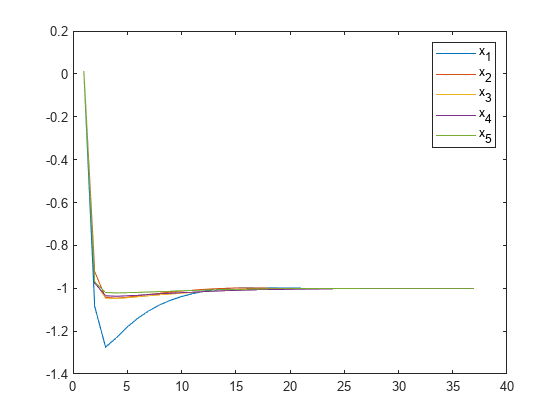

x=x(:,1:k-1);
t=1:k-1;
figure()
plot(t,x)
legend('x_1','x_2','x_3','x_4','x_5');

**(c)** Consider again that $X=\Re$, but $A\left(t\right)$ is time-varying. Solve the problem using Matlab/Python. Show the evolution of the iteration $x_i \left(k\right)\;\textrm{vs}\;k$

%parameters
rho=0.6; %arbitrary choice
N=5; %number of nodes
alpha=0.5; %stepsize of gradient ascend 
%Initial conditions
z=rand(1,100);
mu=zeros(5,100);
mu(:,1)=max(0,rand(5,1)); %Initial values for each mu. There's a mu for each restriction xi-z=0
x=zeros(5,100);
x(:,1)=rand(5,1);
%Error
epsilon=1E-3; %Minimum difference between x and mu
k=1;
A=ones(5);
while(any(abs(x(:,k)-z)>epsilon))
    %First, find x(k+1) for all the nodes
    for i=1:N
        x(i,k+1)=((rho/2)*z(k)-2*i-mu(i,k))/(2*i+rho/2);
    end    
    Matrix=zeros(5);
    alpha=rand(1);
    gradf=@(i)2*i*(1-alpha*x(i,k));
    M=2*[0 gradf(1) gradf(1) 0 0;
     gradf(2) 0 gradf(2) 0 0;
     gradf(3) gradf(3) 0 gradf(3) 0;
     0 0 gradf(4) 0 gradf(4);
     0 0 0 gradf(5) 0];
    Ai=inv(M.*x(:,k))*x(:,k+1);
    A=(M.*Ai).*A;

    z(k+1)=(1/N)*(sum(x(:,k+1))+(1/rho)*mu(i,k));
    for i=1:N
        mu(i,k+1)=mu(i,k)+alpha*(x(i,k+1)-z(k+1));
        mu(i,k+1)=max(0,mu(i,k+1));
    end
    k=k+1;

end

With the convergence assured, the A is finally:

A

A = 1.0e+06 *

         0    0.0000    0.0000         0         0
   -0.0000         0   -0.0000         0         0
    0.5964    0.5964         0    0.5964         0
         0         0   -0.0000         0   -0.0000
         0         0         0    2.6020         0


The states in the nodes throw time are: 

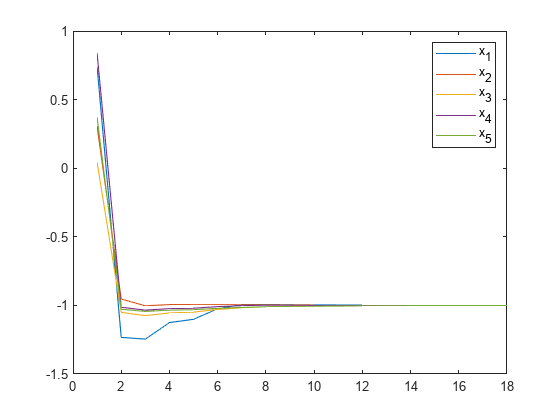

x=x(:,1:k-1);
t=1:k-1;
figure()
plot(t,x)
legend('x_1','x_2','x_3','x_4','x_5');